clear all; close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

C = [C; C; C] %making square matrix out of C 

C =      0     1     0
     0     1     0
     0     1     0




%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 10; %max rough bisection steps

high = 100;
low = 1e-3;

Flow_stable = logical
   0


%setting bounds based on expected stability of the solution
lb_tau = 0.01;
ub_tau = 100;
d_tau = 1e-8;

% Set initial loop values
lbf_tau = NaN;
ubf_tau = NaN;

%tracking variables
tau_track = [];
tau_max = 1e4;
for i = 1:ii
    %Computing cvar and dvar using bisection
    tau = bisection(lb_tau,ub_tau,lbf_tau,ubf_tau);
    cvar = -1;
    dvar = -tau *cvar;

    %setting LMI conditions
    cond1 = A'* Pvar - Qvar' + Pvar*A - Qvar <= -cvar * Pvar;
    cond2 = [ exp(-dvar)*Pvar,  J'*Pvar - Zvar';
        Pvar*J - Zvar,     exp(dvar)*Pvar];

    %positive definite condition
    Lp = Pvar >= 1e-9;

    % combine constraints into one object
    L = [cond1, cond2, Lp];
    opts = sdpsettings('solver','sdpt3','verbose',0);
    diagnostics = optimize(L,[],opts); % solve the LMI problem

    % Check result
    % pres : Primal constraint residuals
    % dres : Dual constraint residuals
    [pres,~] = check(L);
    [ub_tau, lb_tau, lbf_tau, ubf_tau] = CheckFeasibility(tau,ub_tau,lb_tau,lbf_tau,ubf_tau,pres,diagnostics);

    
    %storing iteration
    tau_track(i) = tau;

    if i>1
         %check has minus two because the variable is changed every other cycle
        if abs(tau-tau_track(i-1)) < d_tau
            break;
        end
        if tau > tau_max
            break;
        end
    end

    % Store feasible solution
    if min(pres) > 0 && diagnostics.problem == 0
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end


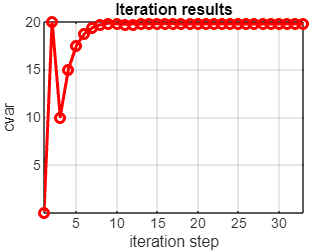


% Plot iteration history
figure(1)
plot(tau_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('tau')
title('Iteration results')
grid on
axis tight



% Retrieve output
P = value(feasible.Pvar)

P =     2.7213   -0.9882   -3.0797
   -0.9882    5.8628    0.7662
   -3.0797    0.7662    7.2190


Q = value(feasible.Qvar)

Q = 1.0e+08 *

    2.4160   -0.0000    0.0000
   -0.0000    2.4160    0.0000
    0.0000    0.0000    2.4160


Z = value(feasible.Zvar)

Z =    -0.0589   -0.5778   -0.7896
   -0.5778    4.7682    2.1973
   -0.7896    2.1973    7.3771



L1  = inv(P) * Q  %L1 times C

L1 = 1.0e+08 *

    1.8141    0.2075    0.7519
    0.2075    0.4416    0.0417
    0.7519    0.0416    0.6510


L2 = J - inv(P)* Z  %L2 times C

L2 =    -0.6604    0.5405    1.5083
   -0.1257    0.0402    0.0390
   -0.6089    0.3055    0.6200



c = value(feasible.cvar)

c = -1

d = value(feasible.dvar)

d = 20.1642



dwelltime = abs(d)/abs(c)

dwelltime = 20.1642